# 3 - Considere um array de tamanho T que serve de base a implementacao de uma memoria associativa (por exemplo em Java). Assuma que a funcao de hash devolve um valor entre 0 e T − 1 com todos os valores igualmente provaveis

## a) a probabilidade de haver pelo menos uma colisao (pelo menos 2 keys mapeadas pela funcao de hash para a mesma posicao do array) se forem introduzidas 10 keys num array de tamanho T = 1000

T = 1000;
keys = 10;
N = 1e5;

valores = randi([0,T - 1],keys, N);
sum = 0;
for a = 1:N
    if length(unique(valores(:,a))) ~= keys
        sum = sum + 1;
    end
end
fprintf("A) %.f%%", sum / N * 100);

A) 4%

## Faca um grafico da probabilidade da alinea a) em funcao do numero de keys para todos os valores relevantes num array de tamanho T = 1000

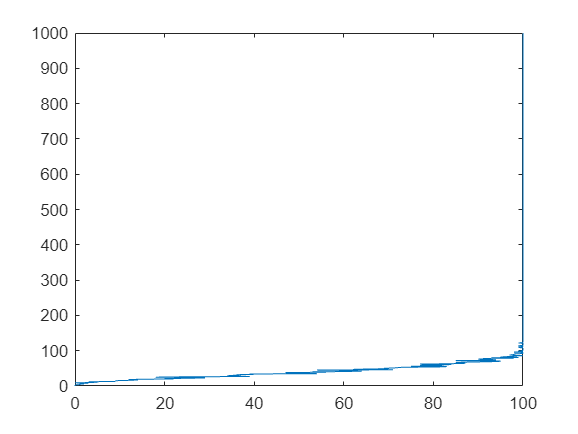

keys = 0:T-1;
N = 1e2;

sum = 0;
probs = [];
for i = 1:T
    valores = randi([0,T - 1],keys(i), N);
    sum = 0;
    for a = 1:N
        if length(unique(valores(:,a))) ~= keys(i)
            sum = sum + 1;
        end
    end
    probs(end + 1) = sum / N * 100;
end

plot(probs, keys) % quantos mais resultados forem possiveis, mais duplicates irao existir

## c) Para um numero de keys igual a 50, represente graficamente a variacao da probabilidade (estimada por simulacao) de nao haver nenhuma colisao em funcao do tamanho T do array (assuma os tamanhos T de 100 ate 1000 com incrementos de 100)

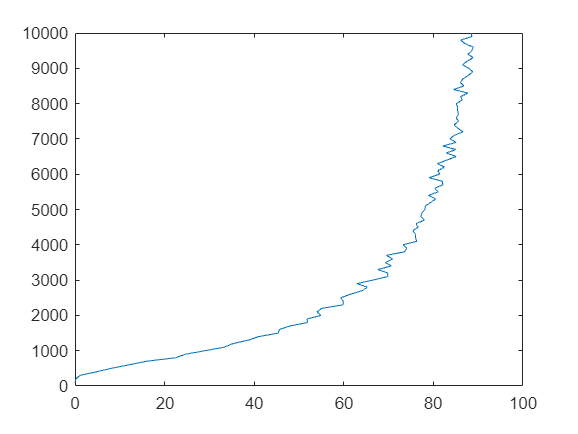

keys = 50;
T = 100:100:1000;
N = 1e3;

sum = 0;
probs = [];
for i = 1:length(T)
    valores = randi([0,T(i) - 1],keys, N);
    sum = 0;
    for a = 1:N
        if length(unique(valores(:,a))) == keys
            sum = sum + 1;
        end
    end
    probs(end + 1) = sum / N * 100;
end

plot(probs, T)